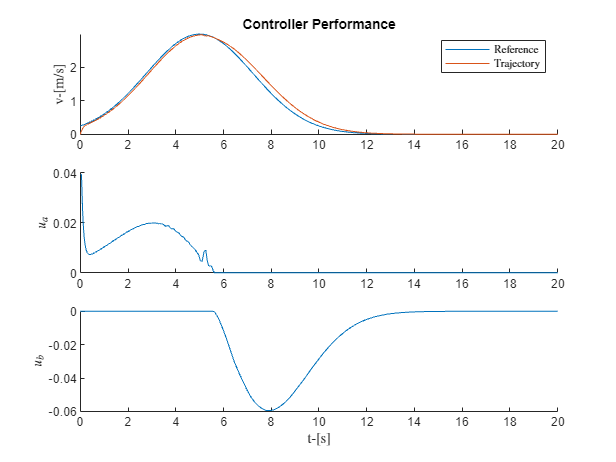

syms t

v_d = 3*exp(-0.1*(t-5)^2);
P.v_d = matlabFunction(v_d,'vars',{'t'});

P.a = 0.1;
P.b = 50;
P.c = 10;

P.v_coast = 0.25;
P.v_dot_max = 9.81/5;

P.v0 = 0;

P.t0 = 0;
P.tf = 20;

P.k_p_brake = 0.25;
P.k_p_accel = 0.25;

[t,v] = ode45(@(t,v) closedLoopDynamics(t,v,P),[P.t0,P.tf], P.v0);

u = [];
for i = 1:length(t)
    u = [u; controller(t(i), v(i),P)];
end

figure()
    subplot(3,1,1)
    hold on
        plot(t,P.v_d(t),"DisplayName",'Reference')
        plot(t,v,"DisplayName",'Trajectory')
    hold off
    legend("Interpreter","latex")
    title("Controller Performance")

    ylabel("v-[m/s]",'Interpreter','latex')
    subplot(3,1,2)
        hold on
            plot(t,u(:,1),"DisplayName","Accelerator")
        hold off
        ylabel("$u_a$",'Interpreter','latex')
    subplot(3,1,3)
        hold on
            plot(t,u(:,2),"DisplayName","Brakes")
        hold off
        ylabel("$u_b$",'Interpreter','latex')
        xlabel("t-[s]",'Interpreter','latex') 

function v_dot = closedLoopDynamics(t,v,P)
    u = controller(t,v,P);
    v_dot = openLoopDynamics(t,v,u,P);
end

function v_dot = openLoopDynamics(t,v,u,P)
    v_dot = -P.a*v + P.b*u(1) + P.c*u(2);
end

function u = controller(t,v,P)
    e = P.v_d(t) - v;
    if e > 0 % Acceleration
        u_a_max = (P.v_dot_max + P.a*v)/P.b;
        u_a = P.k_p_accel*e;
        u_a = max(min([u_a,u_a_max,1]),0);
        u = [u_a, 0];
    else % Braking
        u_b_max = (-P.v_dot_max + P.a*v)/P.c;
        u_b = P.k_p_brake*e;
        u_b =  min(max([u_b,u_b_max,-1]),0);
        u = [0, u_b];
    end
end